**Exercise 2 ECE537 **

**Julie Jiang V00902597**

**Zixuan Deng V00971633**

**Q1**

**Reload the Class A, B and C data from Exercise 1 and generated the Bayes decision boundaries for equal a priori class probabilities.**

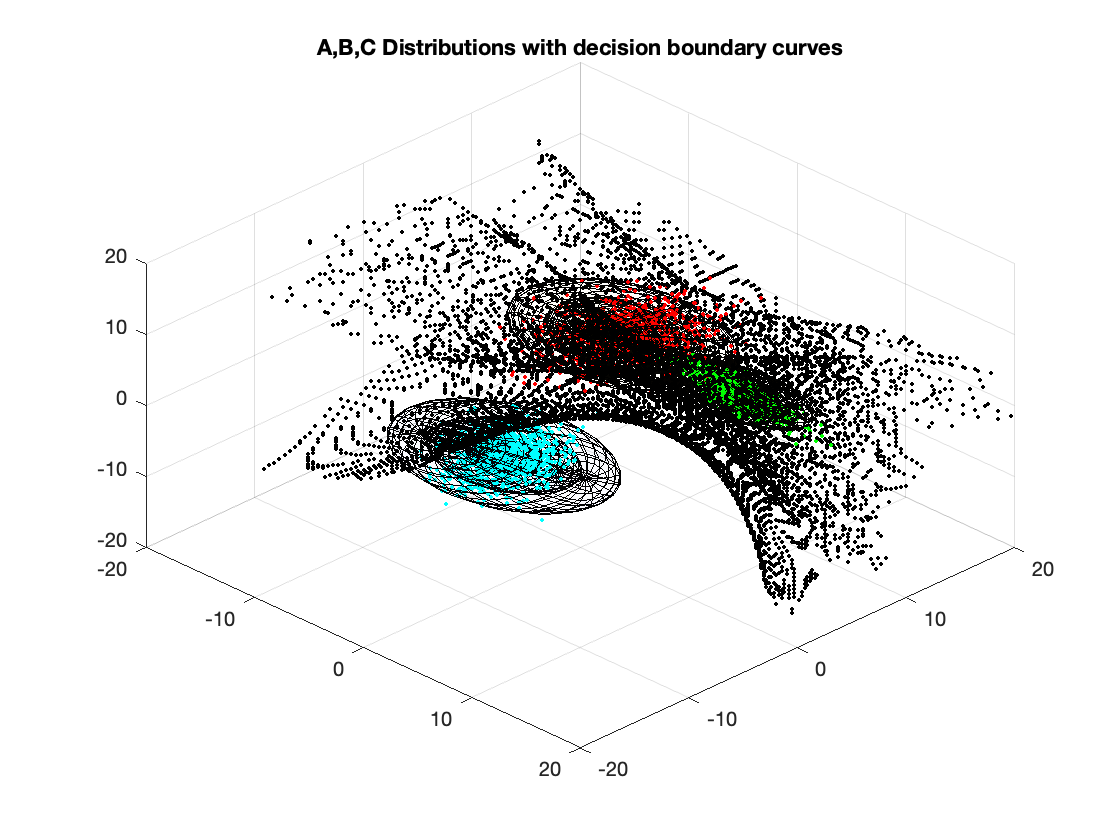

clear all;
% muA=[0 ;4 ;7];
% muB=[10 ;5 ;5];
% muC = [-2; -5; -5];

% First we need to load data, A, B, C. 
muA=[0 4 7];
muB=[10 5 5];
muC = [-2 -5 -5];

covA = [6.5000, 2.1651, 1.2500;
    2.1651, 5.1250, 2.3816;
    1.2500, 2.3816, 2.3750];

covB = [3.0184, 0.4331, -1.4481;
    0.4331, 0.9436, -0.6456;
    -1.4481, -0.6456, 1.2880];

covC = [6.8928, -1.3750, 3.1945;
    -1.3750, 3.3572, 0.6945;
    3.1945, 0.6945, 3.7500];
% Get data A B C. 
A= trans(Gaussion_Data(1000,3,muA, covA), muA, covA);
B= trans(Gaussion_Data(1000,3,muB, covB), muB, covB);
C= trans(Gaussion_Data(1000,3,muC, covC), muC, covC);
% The priori probabilities are all set to 1/3. 
prior_a = 1/3;
prior_b = 1/3;
prior_c = 1/3;
% Build 3D volume of grid points.
box = vol3D([-15 20 -15 20 -15 20],150);

% Get boundaries and plot the boundaries. 
[boundary_AB, boundary_BC, boundary_AC] = bayes_bound(muA,covA,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);

plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB,boundary_BC,boundary_AC,box)
title('A,B,C Distributions with decision boundary curves')

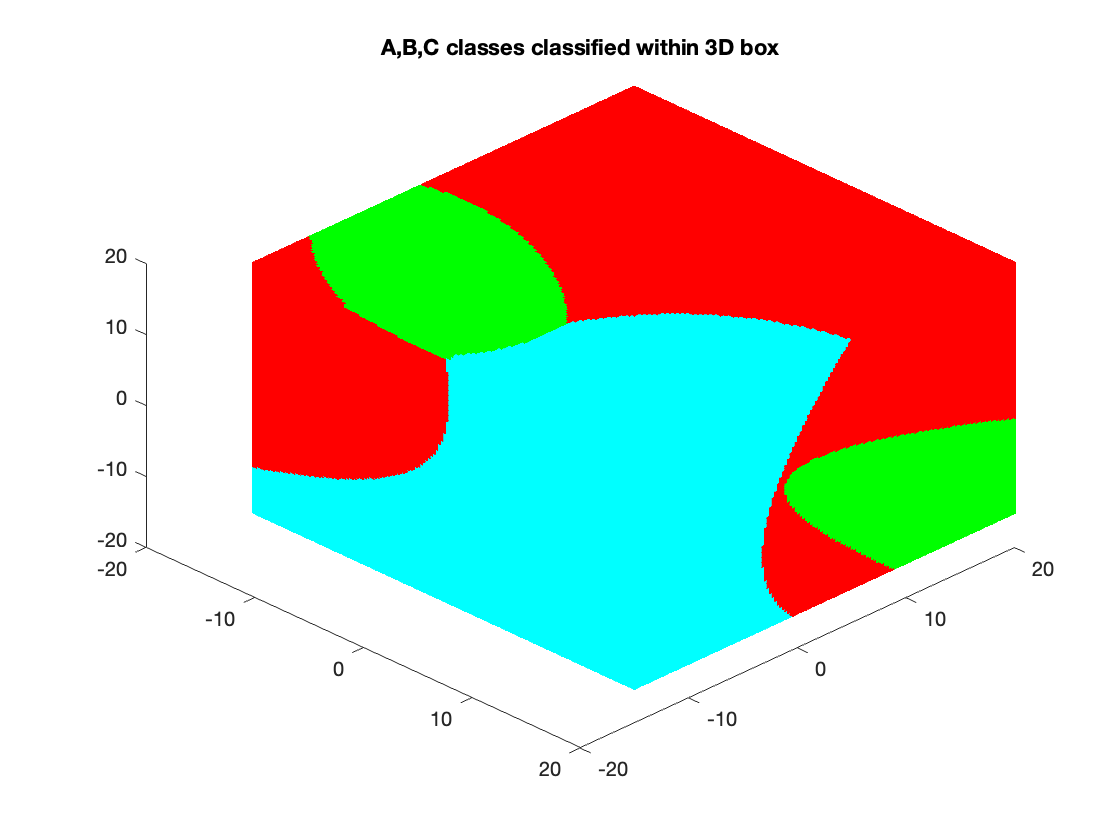




[class_a, class_b, class_c]=classifier(muA,covA,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);
plot_box(class_a,class_b,class_c,box)
title('A,B,C classes classified within 3D box')
hold off;

**Q2**

**Assess the degree to which changes to the means and covariance of the data classes produces changes the nature of the generated inter-class Bayes decision boundaries.**

By changing mean and covariance to observe the change of the boundary, we will do the following three experiments:

1. change mean.

2. change covariance.

3. change both mean and covariance.

According these three experiments to see what kind of change will happen on boundary, and the magnitude of their impact on the boundary, we found that decision boundaries is sensetive. Separate the mean and covariance in two case could see which one change boundary more, make a significatly change in plot.

**Q3 **

**Show the nature of these changes by plotting the 3 data classes and their respective decision boundaries with the same 3-D plot.**

%1. Change mean
muA_2 = muA+1;
muB_2 = muB+1

muB_2 =     11     6     6


muC_2 = muC+1;

% Get new data
A2= trans(Gaussion_Data(1000,3,muA_2, covA), muA_2, covA)

A2 =     0.6500    5.5082    7.4544
   -3.1393    4.0620    5.9647
    5.0964    9.0324   10.4919
    2.1027    4.2699    8.1500
   -0.2458    6.1550    7.9888
    0.2763    6.6745   10.3301
    2.5717    9.1726   11.5363
    0.8007    4.9892    8.6189
   -1.6490    4.4391    7.6654
    2.5197    4.6158    8.3665


B2= trans(Gaussion_Data(1000,3,muB_2, covB), muB_2, covB)

B2 =     8.7190    4.9555    7.3506
   11.5573    5.3202    6.4350
   10.5375    6.7188    6.7479
   13.2363    4.9323    6.1424
    8.5655    5.7448    6.6269
   10.5160    6.9267    5.9851
   11.8934    6.1329    5.6806
   13.1272    6.2077    3.8164
   11.3150    5.0125    6.5646
   13.1622    5.3627    5.1548


C2= trans(Gaussion_Data(1000,3,muC_2, covC), muC_2, covC)

C2 =     2.5825   -2.9539    0.1255
    0.1184   -4.1704   -4.3900
    0.2796   -4.8635   -2.3845
    0.4201   -5.0908   -1.9570
   -3.5438   -3.9728   -5.7777
    2.4793   -4.3548   -1.5215
   -2.7033   -2.8523   -4.0510
    1.4905   -5.4802   -3.0494
   -1.5597   -3.5100   -1.8135
   -4.8831   -4.2760   -7.6788


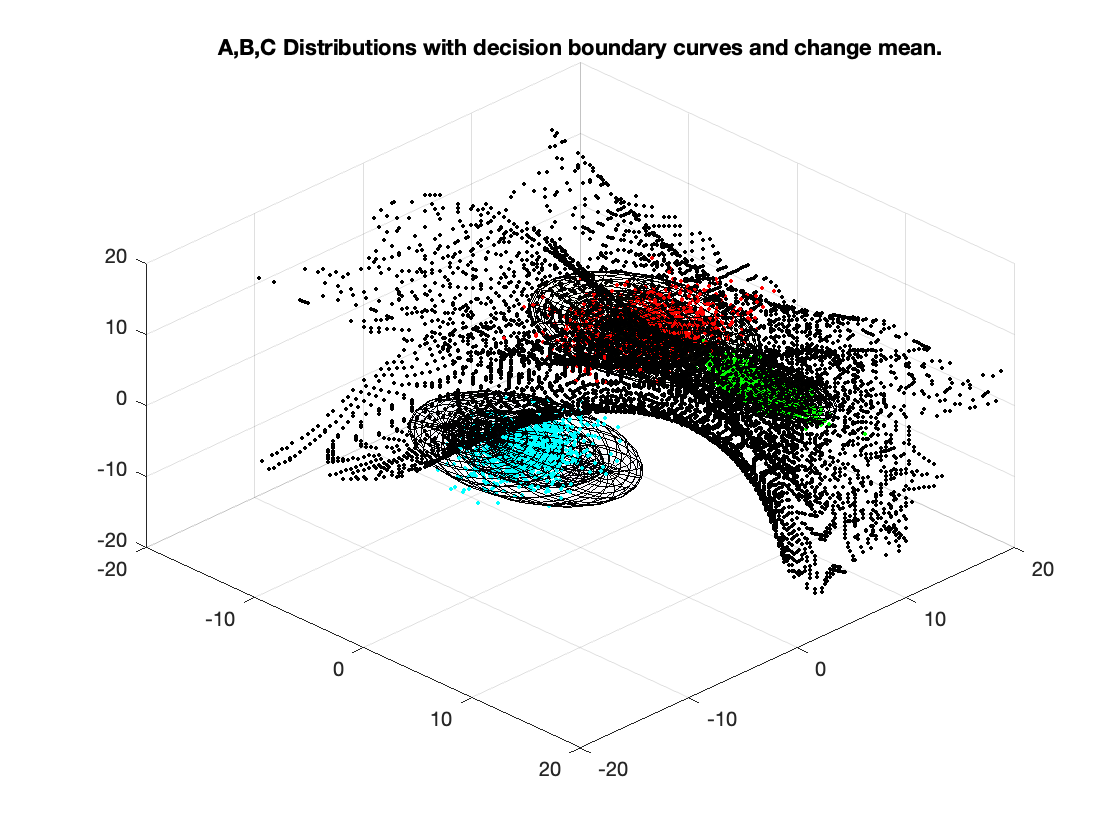


% new decision boundary and plots. 
[boundary_AB_2, boundary_BC_2, boundary_AC_2] = bayes_bound(muA_2,covA,prior_a,muB_2,covB,prior_b,muC_2,covC,prior_c,box);

plot_classes(A2,B2,C2,muA_2,muB_2,muC_2,covA,covB,covC)

plot_boundary(boundary_AB_2,boundary_BC_2,boundary_AC_2,box)
title('A,B,C Distributions with decision boundary curves and change mean.')

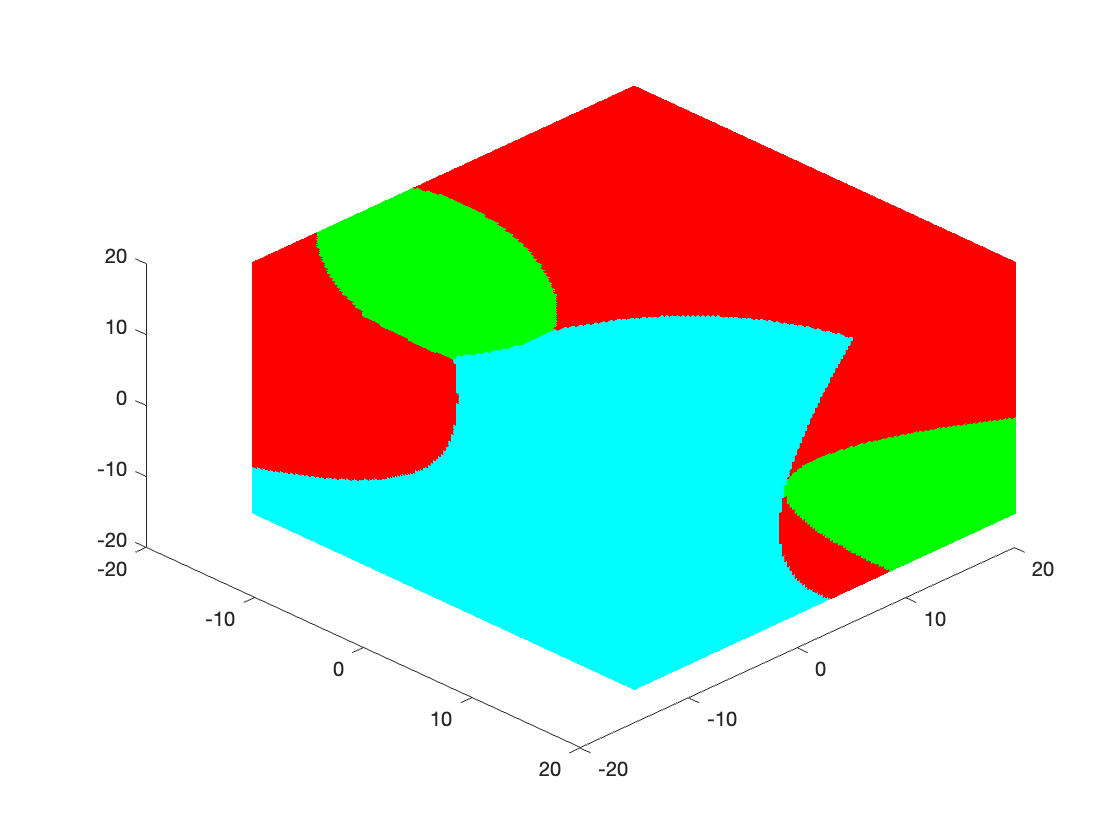



[class_a_2, class_b_2, class_c_2]=classifier(muA_2,covA,prior_a,muB,covB,prior_b,muC_2,covC,prior_c,box);
plot_box(class_a_2,class_b_2,class_c_2,box)
hold off;

% Change covariance

covA_2 = covA+1;
covB_2 = covB+1

covB_2 =     4.0184    1.4331   -0.4481
    1.4331    1.9436    0.3544
   -0.4481    0.3544    2.2880


covC_2 = covC+1;
% new data
A2_2= trans(Gaussion_Data(1000,3,muA, covA_2), muA, covA_2)

A2_2 =    -0.8729    7.1674    9.2208
   -2.6029   -1.9118    4.3792
   -1.9207    5.6144    8.3568
    2.0840    3.2289    5.3664
   -0.7543    4.0898    8.3005
    1.6775    2.7327    5.5385
   -1.6524    0.5301    6.8242
   -0.0614    4.4006    6.7749
    2.4341    4.8795    7.1769
   -4.4343    0.3869    3.7289


B2_2= trans(Gaussion_Data(1000,3,muB, covB_2), muB, covB_2)

B2_2 =     5.8790    5.1782    6.8793
   10.5319    5.5968    2.3896
    6.3668    2.6866    7.3793
   11.1310    3.5554    4.9531
    6.9312    3.5688    5.5849
    8.6457    5.3552    6.7025
    9.1064    5.5946    4.9329
   11.5205    5.7815    1.5960
   10.7129    4.5486    1.9946
   12.4873    8.1589    4.9402


C2_2= trans(Gaussion_Data(1000,3,muC, covC_2), muC, covC_2)

C2_2 =    -5.2518   -4.2689   -6.3523
   -3.7256   -7.0710   -7.5848
   -1.2599   -5.8161   -3.9692
   -5.5451   -5.8549   -8.0995
   -1.3809   -5.0105   -5.5726
   -6.2424   -3.4699   -7.6796
   -0.4308   -1.4252   -0.3471
    2.6810   -3.1743   -1.8946
   -5.6966   -4.1847   -4.2262
   -1.2986   -4.5867   -7.2665


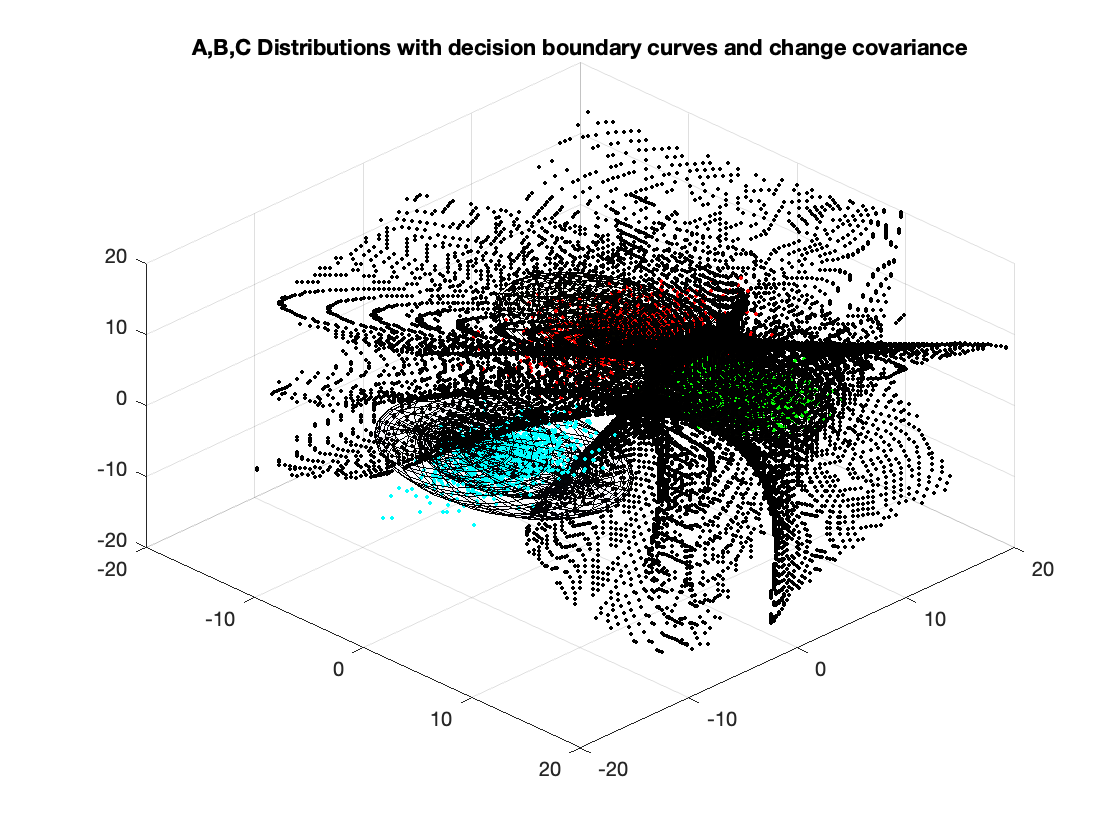


% new decison boundary and plots. 
[boundary_AB_22, boundary_BC_22, boundary_AC_22] = bayes_bound(muA,covA_2,prior_a,muB,covB_2,prior_b,muC,covC_2,prior_c,box);

plot_classes(A2_2,B2_2,C2_2,muA,muB,muC,covA_2,covB_2,covC_2)

plot_boundary(boundary_AB_22,boundary_BC_22,boundary_AC_22,box)
title('A,B,C Distributions with decision boundary curves and change covariance')

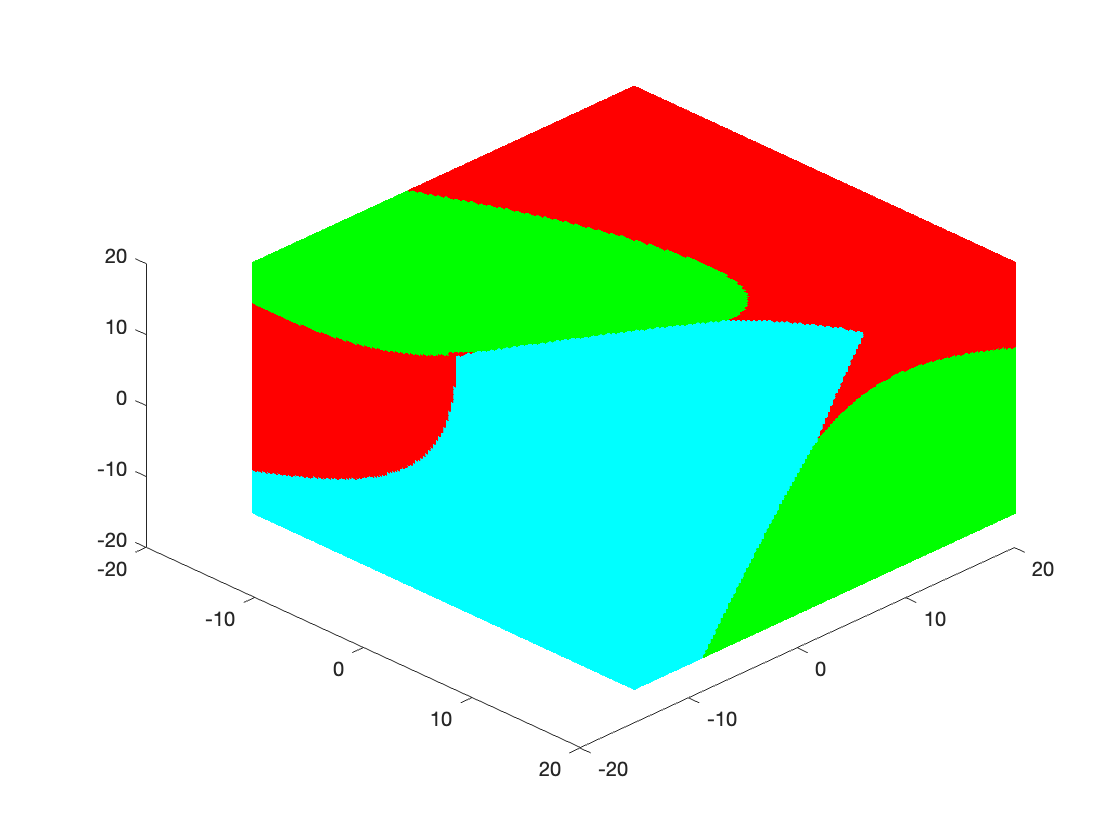



[class_a_22, class_b_22, class_c_22]=classifier(muA,covA_2,prior_a,muB,covB_2,prior_b,muC,covC_2,prior_c,box);
plot_box(class_a_22,class_b_22,class_c_22,box)
hold off;

%Change both mean and covariance
A2_3= trans(Gaussion_Data(1000,3,muA_2, covA_2), muA_2, covA_2)

A2_3 =    -0.5073    6.9014    7.3006
   -1.1010    5.6184    9.2826
   -0.0548    6.2497    7.7014
    4.3331    1.8706    6.0158
    1.7465    5.6867    7.2476
   -1.1170    1.4950    8.2944
   -0.6803    6.4801    9.4393
   -1.5109    4.3696    5.0981
    4.9778    3.1854    7.6672
    4.1659    2.9641    8.4471


B2_3= trans(Gaussion_Data(1000,3,muB_2, covB_2), muB_2, covB_2)

B2_3 =     9.0082    5.9668    5.5407
   10.0615    5.6889    7.3566
    9.5161    5.0999    6.4998
    9.3492    3.8894    3.1310
   10.9559    4.3077    3.7965
   13.8565    5.8120    5.8176
    8.2608    4.9253    4.7037
   11.5388    5.0135    5.8707
    9.7698    4.4483    5.7465
   11.6067    6.4201    5.9235


C2_3= trans(Gaussion_Data(1000,3,muC_2, covC_2), muC_2, covC_2)

C2_3 =    -5.3704   -4.2506   -8.9895
   -1.9721   -4.5519   -4.4854
   -0.8154   -1.6500   -2.5127
   -4.5085   -1.5496   -8.6190
   -1.3938   -2.5779   -4.3408
   -1.1012   -6.2998   -4.5158
   -0.5138   -0.3826   -3.5893
    2.5302   -4.2612   -1.7370
    1.1053   -4.6314   -4.1145
    3.9763   -6.3900   -1.9713


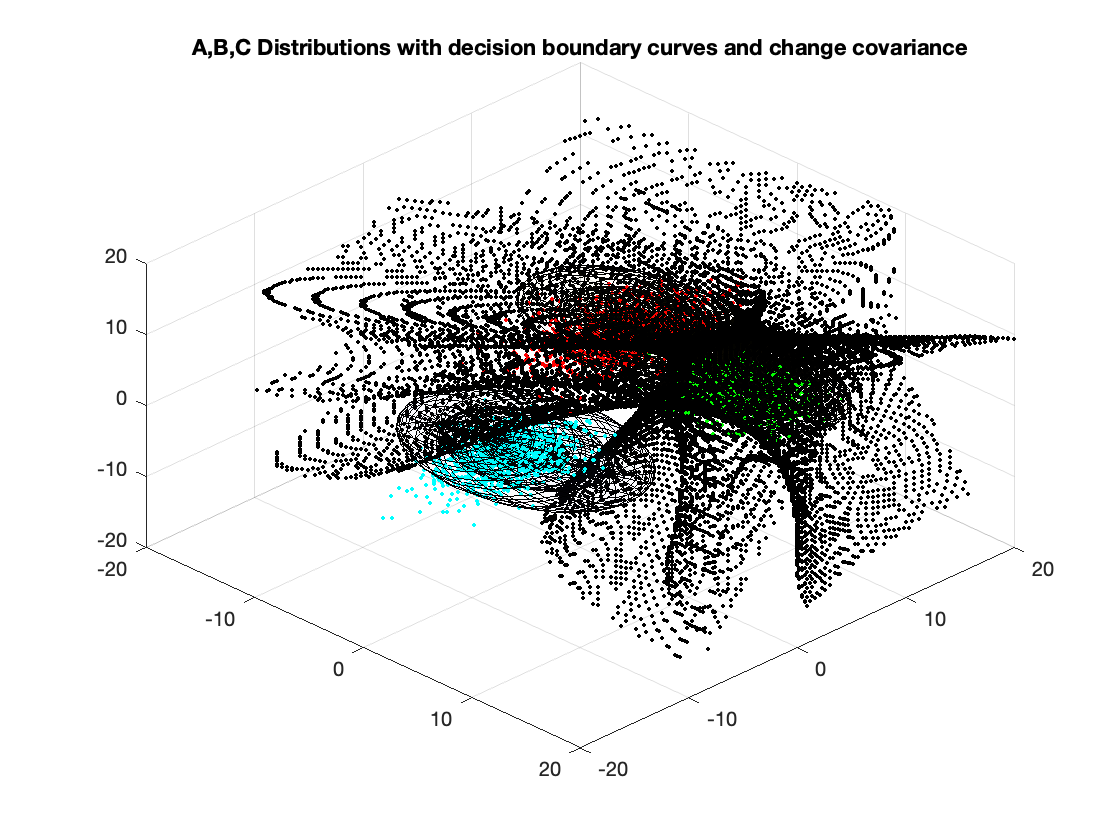



[boundary_AB_23, boundary_BC_23, boundary_AC_23] = bayes_bound(muA_2,covA_2,prior_a,muB_2,covB_2,prior_b,muC_2,covC_2,prior_c,box);

plot_classes(A2_2,B2_2,C2_2,muA_2,muB_2,muC_2,covA_2,covB_2,covC_2)

plot_boundary(boundary_AB_23,boundary_BC_23,boundary_AC_23,box)
title('A,B,C Distributions with decision boundary curves and change covariance')

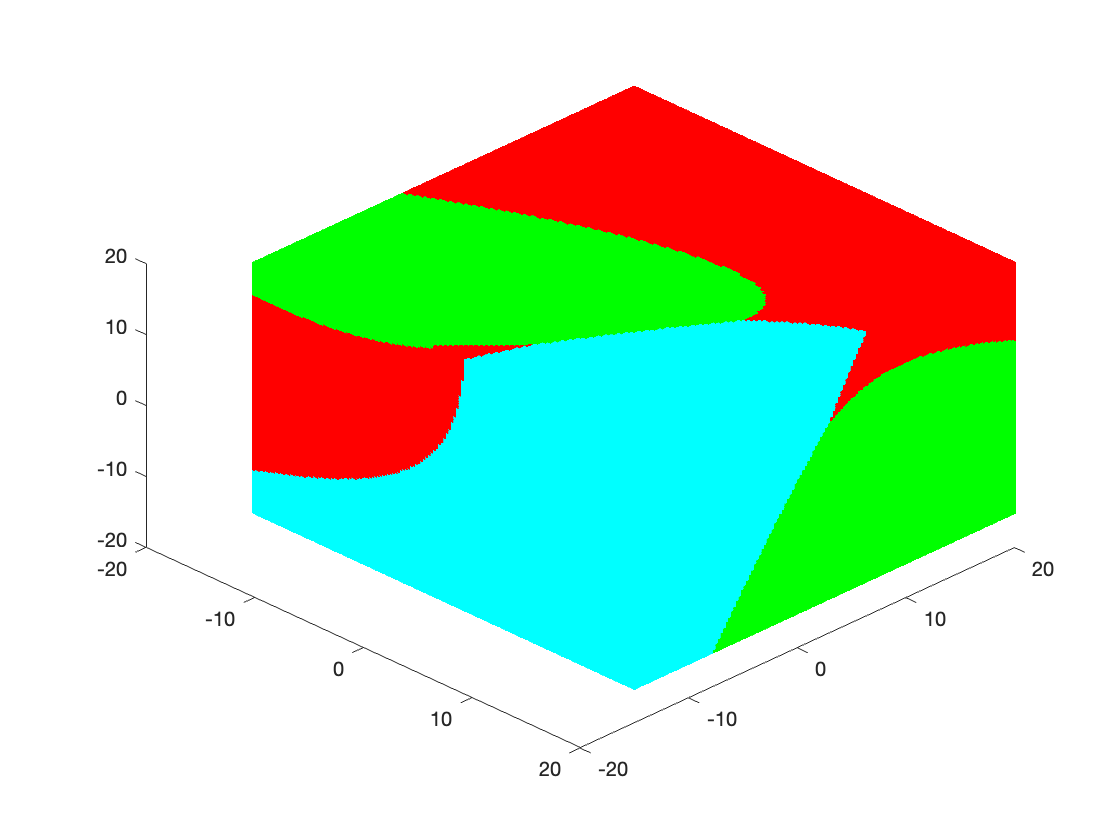



[class_a_23, class_b_23, class_c_23]=classifier(muA_2,covA_2,prior_a,muB_2,covB_2,prior_b,muC_2,covC_2,prior_c,box);
plot_box(class_a_23,class_b_23,class_c_23,box)
hold off;

Based on the above three experiment, the change of covariance has signifcantly change in boundary. Also, change both mean and covariance has huge change in plot. The change of the mean, does not have huge change. However, if we change mean to totally different number(not +1 and -1), may have different result.

**Q4**

**Assess how these decision boundaries change with changes to the three class’s a priori probabilities**.

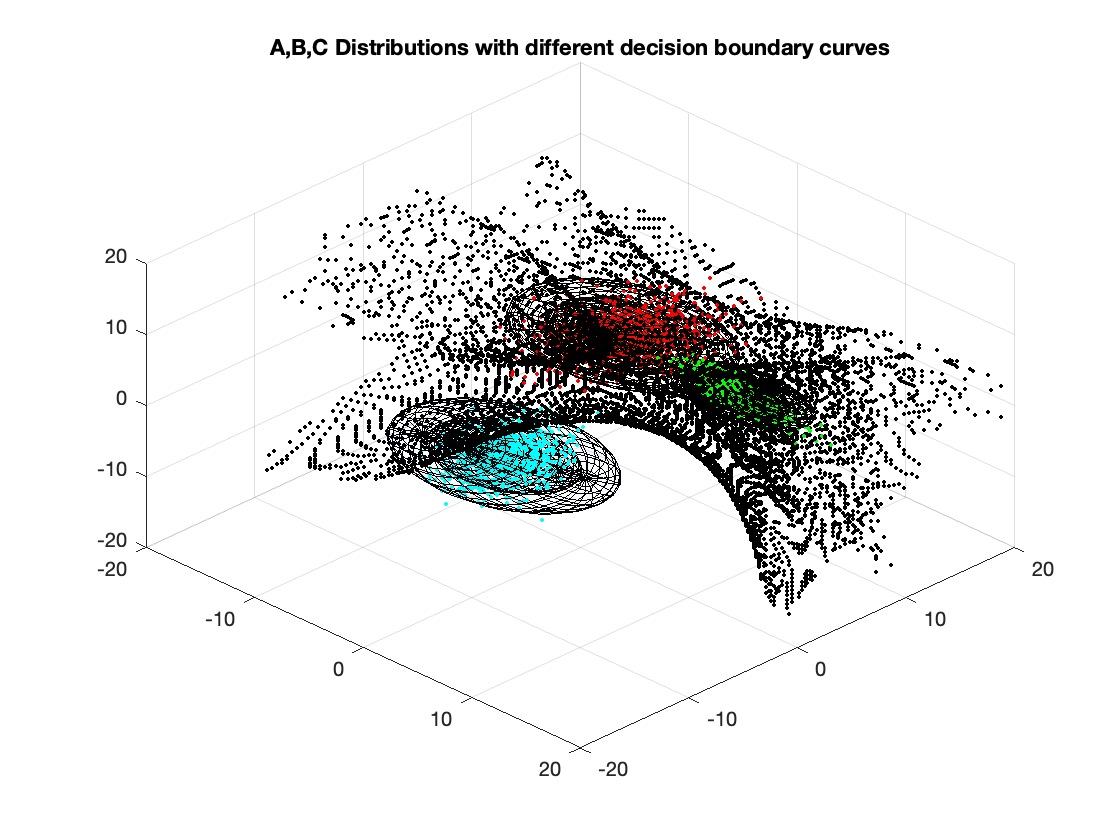

%change the priori probability.
prior_a_new = 0.7;
prior_b_new = 0.01;
prior_c_new = 0.29;

[boundary_AB_3, boundary_BC_3, boundary_AC_3] = bayes_bound(muA,covA,prior_a_new,muB,covB,prior_b_new,muC,covC,prior_c_new,box);



plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_3,boundary_BC_3,boundary_AC_3,box)
title('A,B,C Distributions with different decision boundary curves')

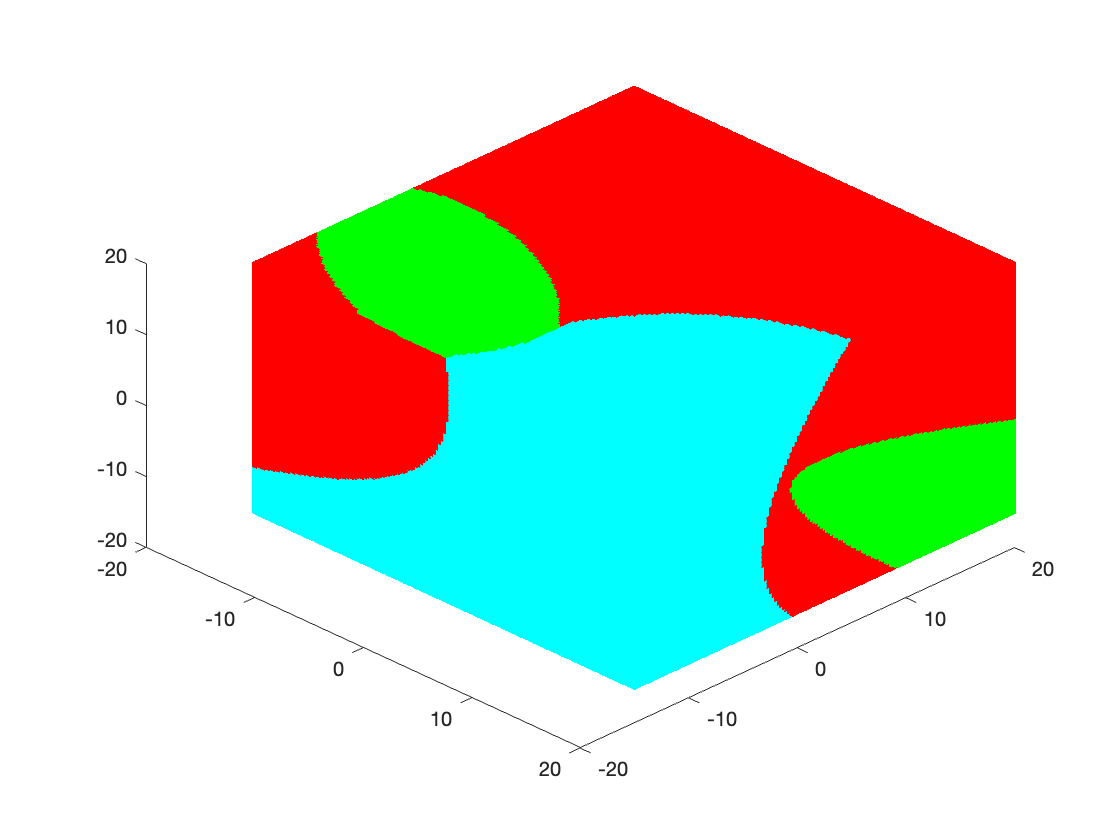


[class_a_3, class_b_3, class_c_3]=classifier(muA,covA,prior_a_new,muB,covB,prior_b_new,muC,covC,prior_c_new,box);
plot_box(class_a_3,class_b_3,class_c,box)

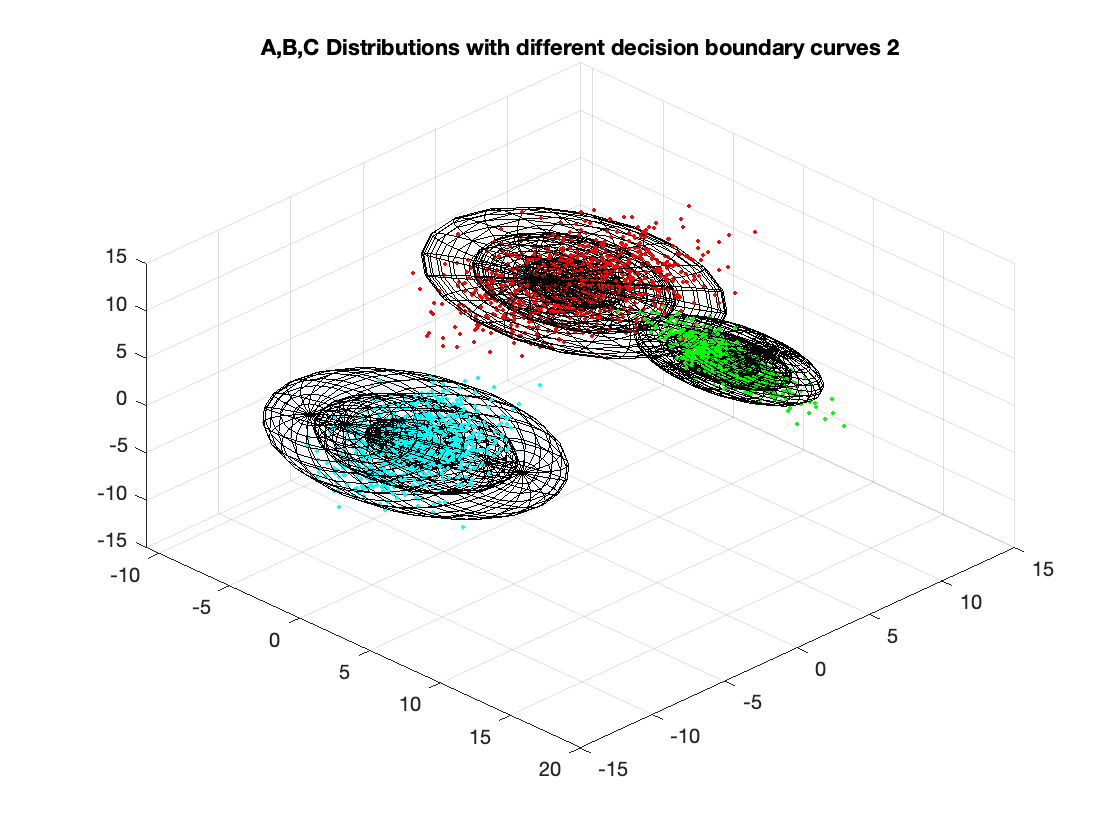

%change the priori probability to see the boundary work or not.
prior_a_new = 1;
prior_b_new = 0;
prior_c_new = 0;

[boundary_AB_3, boundary_BC_3, boundary_AC_3] = bayes_bound(muA,covA,prior_a_new,muB,covB,prior_b_new,muC,covC,prior_c_new,box);



plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)

plot_boundary(boundary_AB_3,boundary_BC_3,boundary_AC_3,box)
title('A,B,C Distributions with different decision boundary curves 2')

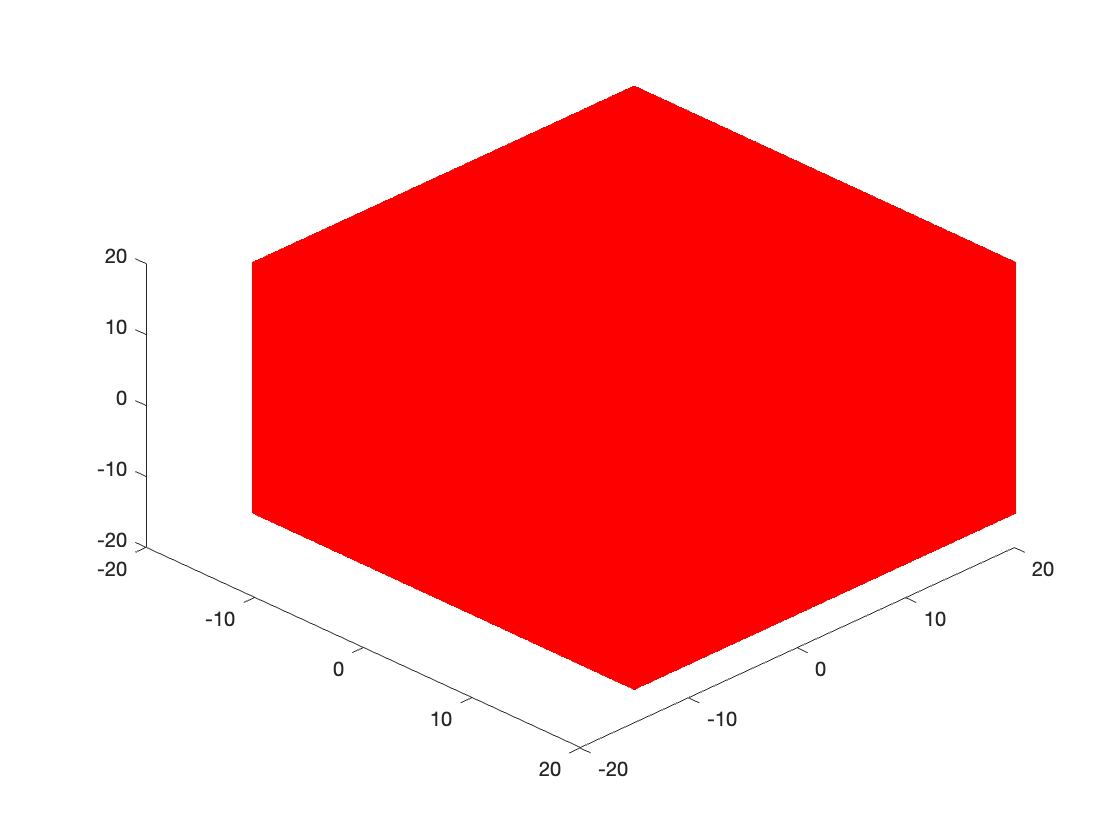


[class_a_3, class_b_3, class_c_3]=classifier(muA,covA,prior_a_new,muB,covB,prior_b_new,muC,covC,prior_c_new,box);
plot_box(class_a_3,class_b_3,class_c_3,box)

We actually do not see too much change until we change one prior probability to 1. When prior probability of a change to 1, there's only one color in the plot. This experiment follows Bayesian Theorem. 

**Q5 **

% lambda_aa, lamdba_ab, lambda_ac
loss_a = [0 4 1];
% lambda_ba, lambda_bb, lambda_bc
loss_b = [4 0 10];
% lambda_ca, lambda_cb, lambda_cc
loss_c = [1 10 2];


p_x_wka = likelihood_f(box,muA,covA);
% p_wka_x = posterior_probability(N,prior_a, p_x_wka); 

p_x_wkb = likelihood_f(box,muB,covB);
% p_wkb_x = posterior_probability(N,prior_b, p_x_wkb);

p_x_wkc = likelihood_f(box,muC,covC);
% p_wkc_x = posterior_probability(N,prior_c, p_x_wkc);

p_probs = [p_x_wka, p_x_wkb, p_x_wkc];
p_probs = p_probs.';

r_a = expected_loss_f(loss_a, p_probs)

r_a =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


r_b = expected_loss_f(loss_b, p_probs) 

r_b =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


r_c = expected_loss_f(loss_c, p_probs)

r_c =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


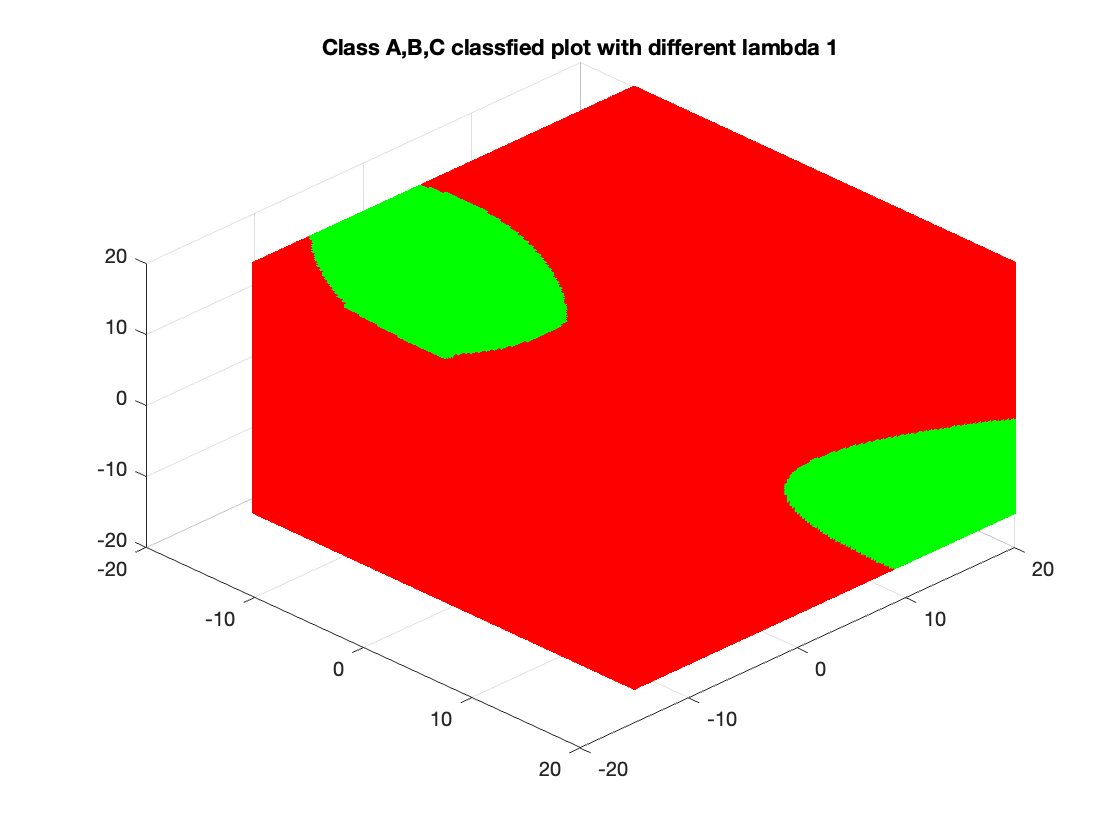


% plot_classes(A,B,C,muA,muB,muC,covA,covB,covC) 
% hold off
% plot_loss_boundary(r_a, r_b, r_c, box)
% title('A,B,C Distributions decision boundary curves with different lambda 1')


plot_loss(box, r_a, r_b, r_c)
title('Class A,B,C classfied plot with different lambda 1')

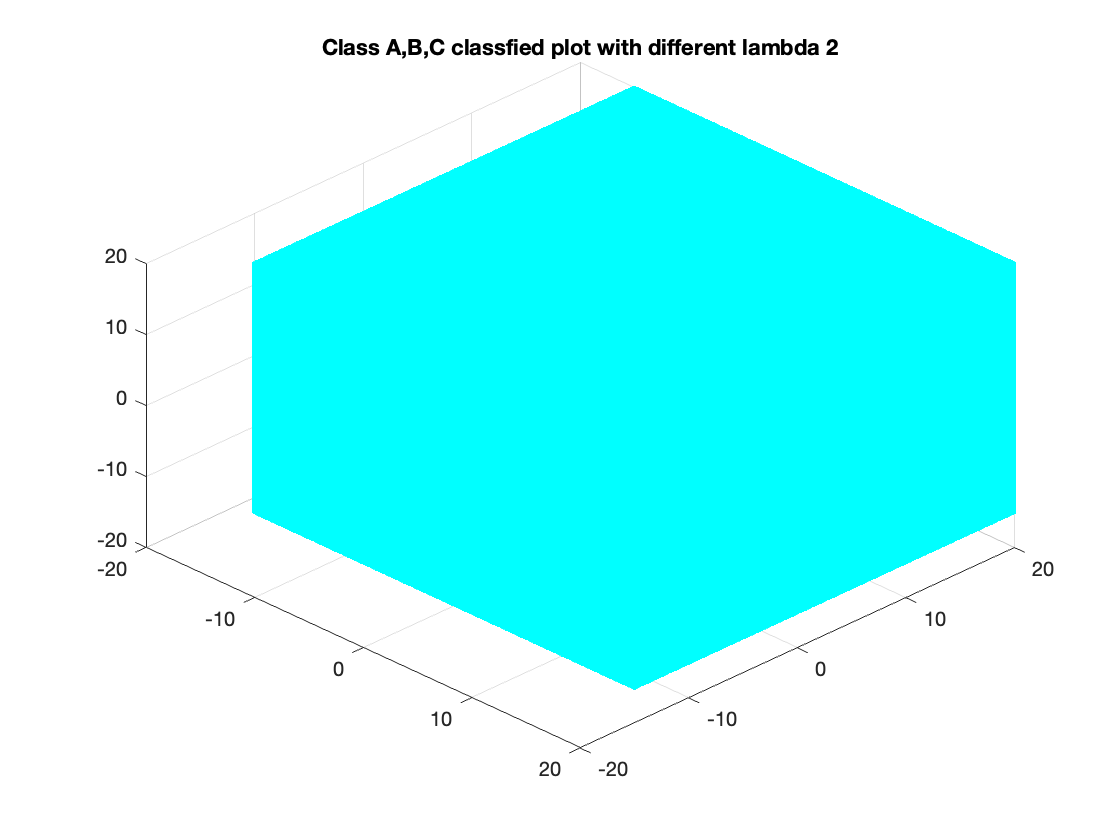

loss_a_1 = [0 4 1];
loss_b_1 = [4 0 10];
loss_c_1 = [1 10 -inf];


p_x_wka_1 = likelihood_f(box,muA,covA);
% p_wka_x = posterior_probability(N,prior_a, p_x_wka); 

p_x_wkb_1 = likelihood_f(box,muB,covB);
% p_wkb_x = posterior_probability(N,prior_b, p_x_wkb);

p_x_wkc_1 = likelihood_f(box,muC,covC);
% p_wkc_x = posterior_probability(N,prior_c, p_x_wkc);

p_probs_1 = [p_x_wka_1, p_x_wkb_1, p_x_wkc_1];
p_probs_1 = p_probs_1.';

r_a_1 = expected_loss_f(loss_a_1, p_probs_1);
r_b_1 = expected_loss_f(loss_b_1, p_probs_1); 
r_c_1 = expected_loss_f(loss_c_1, p_probs_1);


% r_c_1(20)

% plot_classes(A,B,C,muA,muB,muC,covA,covB,covC)
% hold off
% plot_loss_boundary(r_a, r_b, r_c, box)
% title('A,B,C Distributions decision boundary curves with different lambda 2')

plot_loss(box, r_a_1, r_b_1, r_c_1)
title('Class A,B,C classfied plot with different lambda 2')

We found that when the class loss function change significantly, the decision boundary will change a lot. It does make sense because when one loss function change significantly, it's expected risk will change a lot, and those it may more safe or dangerous to make the decision, and hence the decision boundary change. However, if the loss function are all 0 and 1, there's no obvious change for the decison boundary.  

Q6

% For 10 standard deviations
std = 10;
outlier = outliers(std, A, muA, covA);
outlier_11 = outlier(1, :);
new_data = [A; outlier_11];

mean_newA = mean(new_data) % recalculate mean

mean_newA =    -0.0797    3.9673    7.0568


cov_newA = cov(new_data) % recalculate covariance

cov_newA =    12.8526    4.7749   -3.2806
    4.7749    6.1927    0.5188
   -3.2806    0.5188    5.5988


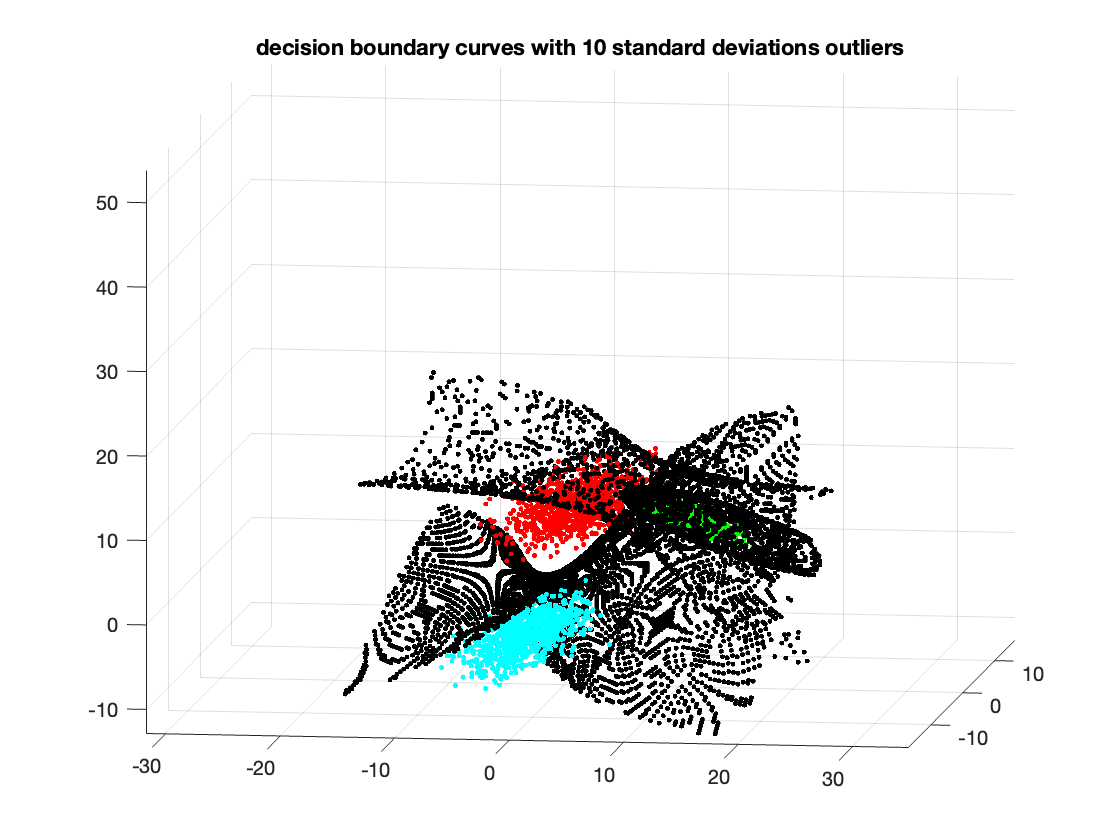



[boundary_AB_77, boundary_BC_77, boundary_AC_77] = bayes_bound(mean_newA,cov_newA,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);

% plot_classes(new_data,B,C,mean_newA,muB,muC,cov_newA,covB,covC)
scatter3(new_data(:, 1), new_data(:, 2), new_data(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])




plot_boundary(boundary_AB_77,boundary_BC_77,boundary_AC_77,box)
title('decision boundary curves with 10 standard deviations outliers')

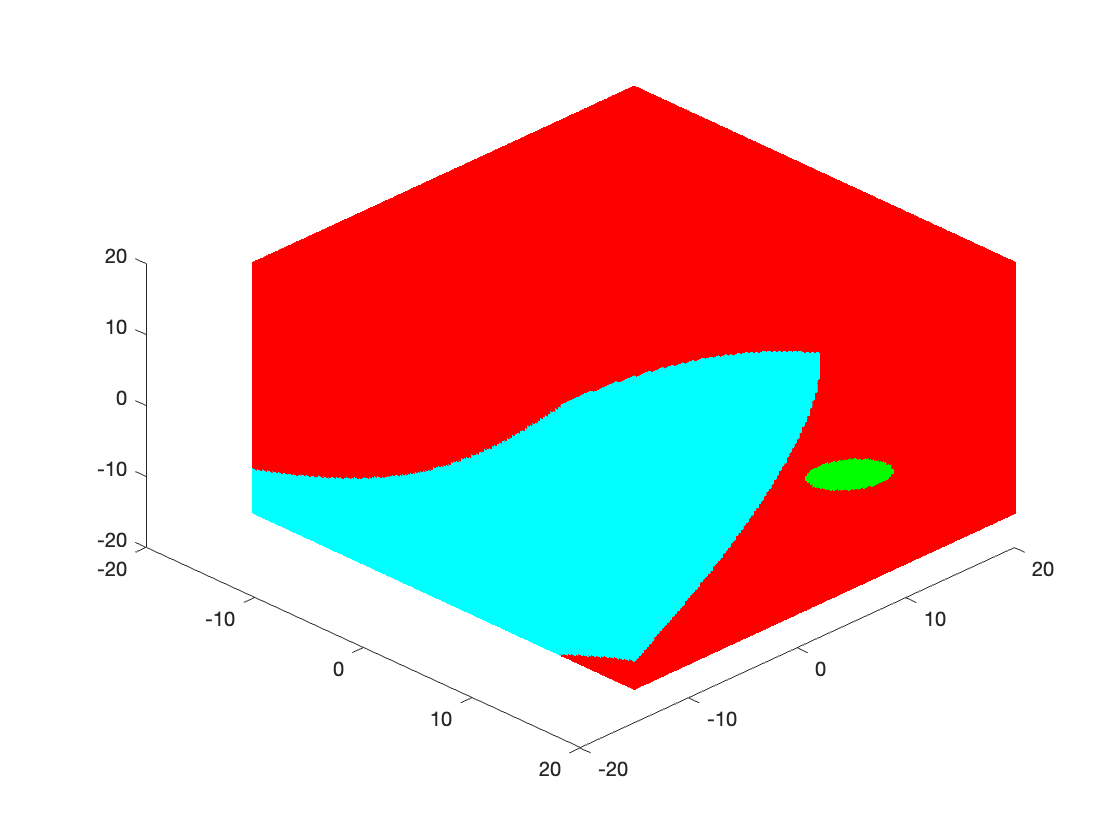




[class_a_4, class_b_4, class_c_4]=classifier(mean_newA,cov_newA,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);
plot_box(class_a_4,class_b_4,class_c_4,box)
hold off;



% For 50 standard deviations
std_1 = 50;
outlier_1 = outliers(std_1, A, muA, covA);
outlier_m = outlier_1(1, :);
new_data_1 = [A; outlier_m];

mean_newA_1 = mean(new_data_1) % recalculate mean

mean_newA_1 =    -0.3985    3.8363    7.2839


cov_newA_1 = cov(new_data_1) % recalculate covariance

cov_newA_1 =   165.4718   67.4620 -111.9862
   67.4620   31.9410  -44.1311
 -111.9862  -44.1311   83.0261


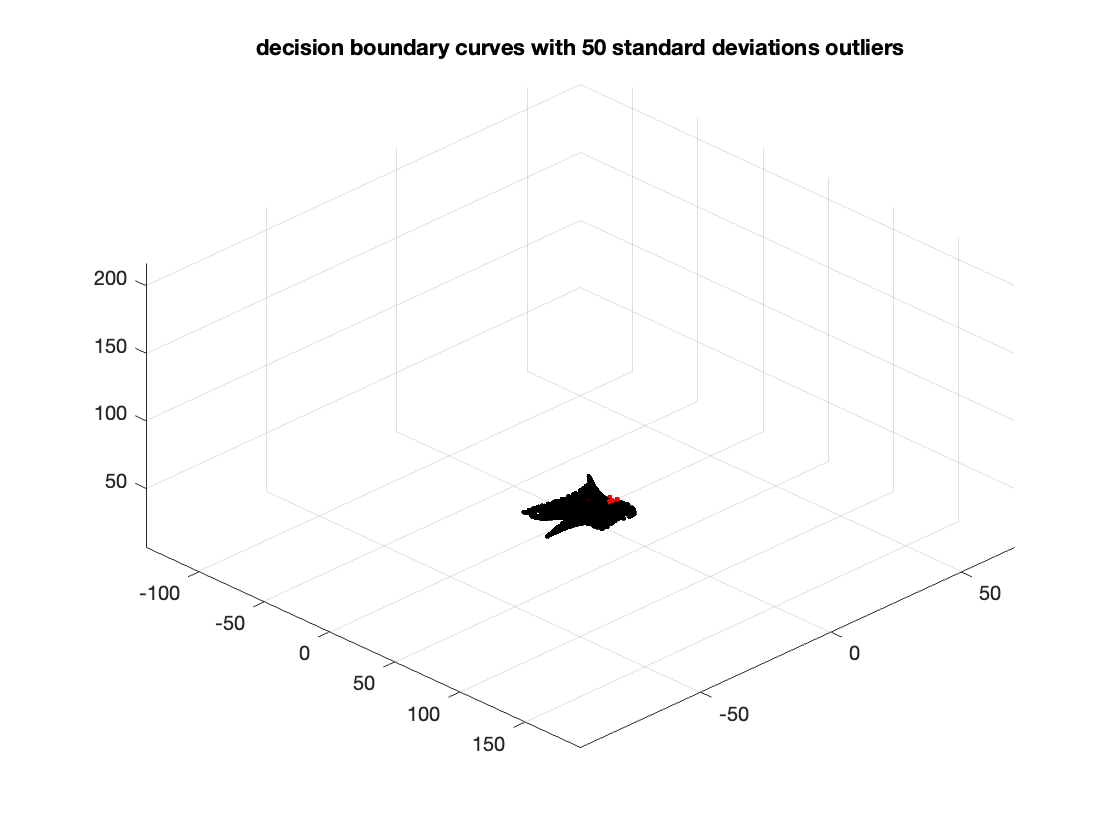



[boundary_AB_8, boundary_BC_8, boundary_AC_8] = bayes_bound(mean_newA_1,cov_newA_1,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);

% plot_classes(new_data_1,B,C,mean_newA_1,muB,muC,cov_newA_1,covB,covC)

scatter3(new_data_1(:, 1), new_data_1(:, 2), new_data_1(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])


plot_boundary(boundary_AB_8,boundary_BC_8,boundary_AC_8,box)
title('decision boundary curves with 50 standard deviations outliers')

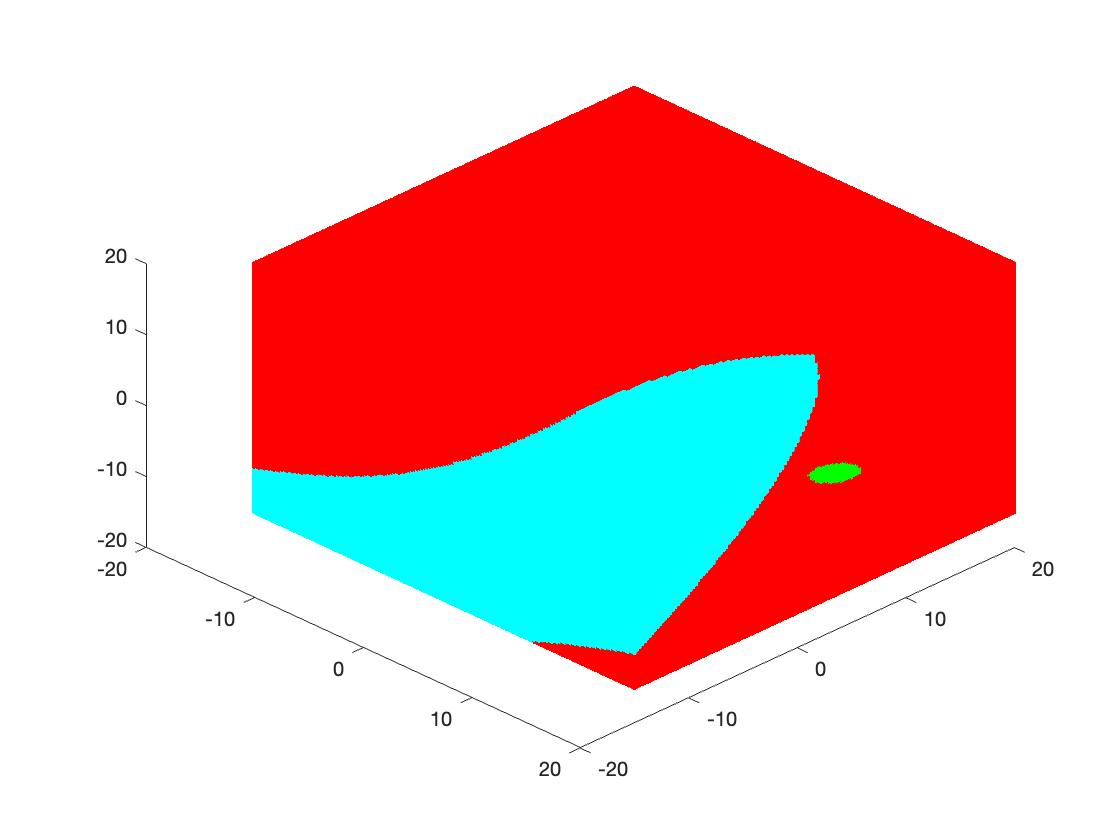



[class_a_5, class_b_5, class_c_5]=classifier(mean_newA_1,cov_newA_1,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);
plot_box(class_a_5,class_b_5,class_c_5,box)
hold off;



% For 100 standard deviations
std_2 = 100;
outlier_2 = outliers(std_2, A, muA, covA);
outlier_22 = outlier_2(1,:);
new_data_2 = [A; outlier_22];

mean_newA_2 = mean(new_data_2) % recalculate mean

mean_newA_2 =    -0.7970    3.6726    7.5677


cov_newA_2 = cov(new_data_2) % recalculate covariance

cov_newA_2 =   642.4068  263.3593 -451.6910
  263.3593  112.4042 -183.6622
 -451.6910 -183.6622  324.9864


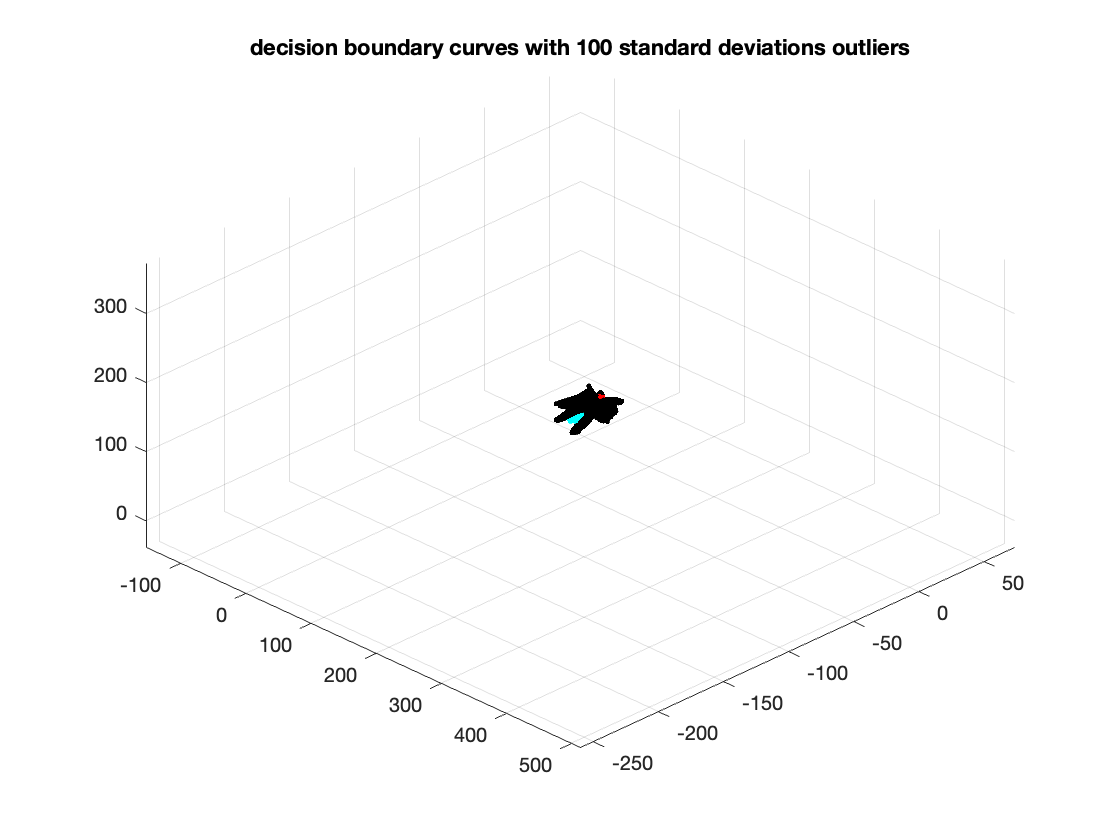



[boundary_AB_9, boundary_BC_9, boundary_AC_9] = bayes_bound(mean_newA_2,cov_newA_2,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);

% plot_classes(new_data_2,B,C,mean_newA_2,muB,muC,cov_newA_2,covB,covC)

scatter3(new_data_2(:, 1), new_data_2(:, 2), new_data_2(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])


plot_boundary(boundary_AB_9,boundary_BC_9,boundary_AC_9,box)
title('decision boundary curves with 100 standard deviations outliers')

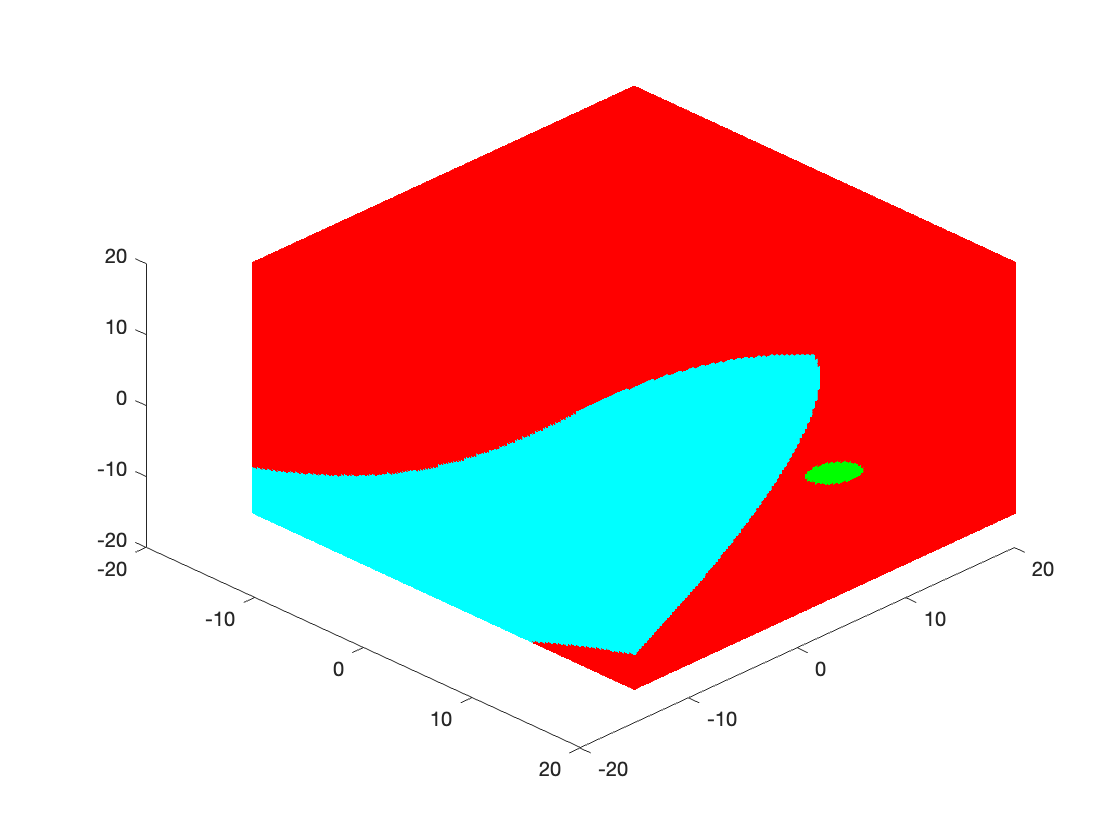




[class_a_6, class_b_6, class_c_6]=classifier(mean_newA_2,cov_newA_2,prior_a,muB,covB,prior_b,muC,covC,prior_c,box);
plot_box(class_a_6,class_b_6,class_c_6,box)
hold off;

Notes: The boudary may not see clear because the outliers point. Please enlarge the plots to see change. 

From graph, we actually do see there are a lot change of decison boundary with even single outlier. When compare decision boundary with 10 standard deviations outliers and the original decison boundary, we found as the outliers appear in class A, more spaces have been classfied as Class A (red areas). And when we draw the o1utliers with higher standard deviation Mahalanobis distance from that class's mean, the more points and area are classified to that class with outliers. This inverstigation tells us that the outliers will change the decison boundary a lot, so when build real models, we need to take care of the outliers and don't let them influence the pattern of data. 

**Q7**

**For real-world data analysis problems, **

**(a) Could the nature of the class decision boundaries effective be driven by only a few data points within the data? **

Yes, driven by only a few data points within the data can change the mean and covariance of the data. Then, the nature of the class decision boundaries is effective changed.

**(b) Is it correct (or appropriate) to have decision boundaries that exhibit high sensitivities to only a small number of data samples? **

Not sure, the decision boundaries not always has exhibit high senseitives to small number of data samples. Also, there are different type outlier exist in the data, the decision boundaries may has high sensitivies due to outliers. Therefore, we need to idenitfy and resolve the outlier at the beginning.

**(c) How would you detect this? **

The outlier have different type.

- We can use Mahalanobis distance to calculate the distance for the data points, and detect the outlier.

- If the data is time serise, we can do the detrend to remove outlier, such as hpfilter.

**(d) How would you resolve this?**

- we can use transform the data

- we can use PCA

- separate or remove outlier.

Function used in A2

function data = Gaussion_Data(k, d, mu, cov)

data  = randn(k,d);
[E,v] = eigs(cov);
data = v^(1/2) * E * data.';
data = data.' + mu;
end



function transform = trans(data,m,sigma)
%     [e2, v2] = eig(cov(data));
%     A = e2 * 1/sqrt(v2);
%     transform = data * A;

%%whitening transformation to get covariance matrix to identity matrix. 
data = data-mean(data);
[E,v] = eigs(cov(data));
Y = E*v^(-1/2);
X = data * Y;

%%coloring transformation to get the exact mean and covariance matrix. 
[E1,v1] = eigs(sigma);
Y = v1^(1/2) * X';
transform = E1 * Y;
transform = transform'+m;
end


function [boundary_ab, boundary_bc, boundary_ac] = bayes_bound(mua,cova,priora,mub,covb,priorb,muc,covc,priorc,box)
epsilon =  0.1; % if epsilon is small like 0.00001, abs(gk_a-gk_b) will be 0 show in Matlab.
gk_a = discriment_f(box,priora, mua, cova);
gk_b = discriment_f(box,priorb, mub, covb);
gk_c = discriment_f(box,priorc, muc, covc);

boundary_ab = find(abs(gk_a-gk_b)<=epsilon);
boundary_bc = find(abs(gk_b-gk_c)<=epsilon);
boundary_ac = find(abs(gk_a-gk_c)<=epsilon);
end



function [class_a, class_b, class_c]=classifier(mua,cova,priora,mub,covb,priorb,muc,covc,priorc,box)
gk_a = discriment_f(box,priora, mua, cova);
gk_b = discriment_f(box,priorb, mub, covb);
gk_c = discriment_f(box,priorc, muc, covc);

class_a = find(gk_a> max(gk_b, gk_c));
class_b = find(gk_b> max(gk_a, gk_c));
class_c = find(gk_c> max(gk_a, gk_b));
end

Discriment Function Formula:

## 
$$g_k \left(\mathit{\mathbf{x}}\right)={\mathit{\mathbf{x}}}^T {\mathit{\mathbf{W}}}_k \mathit{\mathbf{x}}+{\mathit{\mathbf{w}}}_k \mathit{\mathbf{x}}+w_{\textrm{k0}}$$
 
$${\mathit{\mathbf{W}}}_k =-\frac{1}{2}{\Sigma_k }^{-1}$$
 
$${\mathit{\mathbf{w}}}_k ={\Sigma_k }^{-1} \mu_k$$
  
$$w_{\textrm{k0}} =-\frac{1}{2}{\mu_k }^T {\Sigma_k }^{-1} \mu_k -\frac{1}{2}\ln \left|\Sigma_k \right|+\ln \left(P\left(\omega_k \right)\right)$$




function g_x = discriment_f(x,prior_prob, mu, sigma)
% discriment function follows from equation 67 in Ch2.
W_i = (-1/2)*inv(sigma);
w_i = inv(sigma)*mu';
w_i_0 = (-1/2)*mu*inv(sigma)*mu' - (1/2)*log(det(sigma))+log(prior_prob);
g_x = sum((x*W_i.').*x,2).'+w_i'*x'+w_i_0;
g_x = g_x.';


end


function plot_box(a,b,c,box)

classify_a = box(a,:);
classify_b = box(b,:);
classify_c = box(c,:);

plot3(classify_a(:,1),classify_a(:,2),classify_a(:,3),'Marker',".","LineStyle","none","Color",[1 0 0])
hold on
plot3(classify_b(:,1),classify_b(:,2),classify_b(:,3),'Marker',".","LineStyle","none","Color",[0 1 0])
plot3(classify_c(:,1),classify_c(:,2),classify_c(:,3),'Marker',".","LineStyle","none","Color",[0 1 1])
hold off
view([45 45])

end


function plot_classes(A,B,C,muA,muB,muC, covA,covB,covC)

scatter3(A(:, 1), A(:, 2), A(:, 3),'r.')
hold on
scatter3(B(:, 1), B(:, 2), B(:,3),'g.')
scatter3(C(:, 1), C(:, 2), C(:,3),'c.')
view([45, 45])

plot_ellipsoids(muA,covA)
plot_ellipsoids(muB,covB)
plot_ellipsoids(muC,covC)
view([45,45])

end


function plot_boundary(boundary_1, boundary_2, boundary_3, box)

% those plot follows the same logic. 
boundary_1 = box(boundary_1,:);
boundary_2 = box(boundary_2,:);
boundary_3 = box(boundary_3,:);

plot3(boundary_1(:,1),boundary_1(:,2),boundary_1(:,3),'Marker',".","LineStyle","none","Color",[0, 0, 0])
plot3(boundary_2(:,1),boundary_2(:,2),boundary_2(:,3),'Marker',".","LineStyle","none","Color",[0, 0, 0])
plot3(boundary_3(:,1),boundary_3(:,2),boundary_3(:,3),'Marker',".","LineStyle","none","Color",[ 0, 0, 0])

hold off

end


Likelihood function formula :

$p\left(\mathit{\mathbf{x}}\left|\omega_k \right.\right)$ = $\frac{1}{{\left(2\pi \right)}^{\frac{d}{2}} {\left|\Sigma_k \right|}^{\frac{1}{2}} }\exp \left\lbrack {-\frac{1}{2}\left(\mathit{\mathbf{X}}-\mu_k \right)}^T {\Sigma_k }^{-1} \left(\mathit{\mathbf{X}}-\mu_k \right)\right\rbrack \;d=3\;\textrm{in}\;\textrm{our}\;\textrm{case}\ldotp \;$ 

function p_x_wk = likelihood_f(x,mu,cov)
    
    x = x-mu;
    y = inv(cov);
    % equivalent to use dot function in matlab. 
    z = sum((x*y.').*x,2).';
    
    p_x_wk = (1/(((2*pi)^(3/2))*(det(cov))^(1/2)))*exp((-1/2)*z);
    p_x_wk = p_x_wk.';
end


% function p_wk_x = posterior_probability(x,prior_prob, p_x_wk)
%     p_wk_x = p_x_wk * prior_prob / (1 / x);
% end



function r = expected_loss_f(loss, post_probs)
    % we ignore p(w) because they are all same, and p(x) is useless for our
    % case also. Therefore expected loss function simplified to loss
    % function * post probability. 
    % 
    r = loss*post_probs;
end


function plot_loss(data, risk_A, risk_B, risk_C)
    gk_A = - risk_A;
    gk_B = - risk_B;
    gk_C = - risk_C;
    
    boundary_A = find(gk_A > max(gk_B, gk_C));
    boundary_B = find(gk_B > max(gk_A, gk_C));
    boundary_C = find(gk_C > max(gk_A, gk_B));
    
    % Array containing data points for each class
    result_A = data(boundary_A, :);
    result_B = data(boundary_B, :);
    result_C = data(boundary_C, :);
    
    % Plot the region for each class
    scatter3(result_A(:, 1), result_A(:, 2), result_A(:, 3),'r.')
    hold on
    scatter3(result_B(:, 1), result_B(:, 2), result_B(:, 3), 'g.')
    scatter3(result_C(:, 1), result_C(:, 2), result_C(:, 3), 'c.') 
    view([45, 45])
    hold off

end



function plot_loss_boundary(risk_a, risk_b, risk_c, box) % we actually do not use that. find it's not clear to see the boundary. 
    

    epsilon =  0.1; % if epsilon is small like 0.00001, abs(gk_a-gk_b) will be 0 show in Matlab.
    gk_a = -risk_a;
    gk_b = -risk_b;
    gk_c = -risk_c;
    
    boundary_ab = find(abs(gk_a-gk_b)<=epsilon);
    boundary_bc = find(abs(gk_b-gk_c)<=epsilon);
    boundary_ac = find(abs(gk_a-gk_c)<=epsilon);
    
    
    
    boundary_1 = box(boundary_ab,:);
    boundary_2 = box(boundary_bc,:);
    boundary_3 = box(boundary_ac,:);

    plot3(boundary_1(:,1),boundary_1(:,2),boundary_1(:,3),'Marker',".","LineStyle","none","Color",[0, 0, 0])
    plot3(boundary_2(:,1),boundary_2(:,2),boundary_2(:,3),'Marker',".","LineStyle","none","Color",[0, 0, 0])
    plot3(boundary_3(:,1),boundary_3(:,2),boundary_3(:,3),'Marker',".","LineStyle","none","Color",[ 0, 0, 0])

    hold off

end



function m = outliers(std, data, mu, cov)

    [e, v] = eigs(cov);
    data = std' * sqrt(v) * e * data.'; 
    m = data.' + mu;
    
end


% function plot_class_A(a,b,c,box)
% 
% classify_a = box(a,:);
% classify_b = box(b,:);
% classify_c = box(c,:);
% 
% 
% % only plot class A to see the boundary clear. 
% plot3(classify_a(:,1),classify_a(:,2),classify_a(:,3),'Marker',".","LineStyle","none","Color",[1 0 0])
% % hold on
% % plot3(classify_b(:,1),classify_b(:,2),classify_b(:,3),'Marker',".","LineStyle","none","Color",[0 1 0])
% % plot3(classify_c(:,1),classify_c(:,2),classify_c(:,3),'Marker',".","LineStyle","none","Color",[0 1 1])
% % hold off
% view([45 45])
% 
% end


% this function is from A1. 
function m = deTransfer(std, data, mu, cov)
    [E, v] = eigs(cov);
    data = reshape(data, [],3);
    data_1 = std' * sqrt(v) * E * data.';
    m = data_1.' + mu;
    m = [reshape(m(:, 1), 21, 21); reshape(m(:, 2), 21, 21); reshape(m(:, 3), 21, 21)];
    
       
end

function plot_ellipsoids(mu,cov_matrix)
[x,y,z] = ellipsoid(0,0,0,1,1,1);

Std_1_Data = deTransfer(1, [x,y,z], mu, cov_matrix);

n = size(Std_1_Data,2);

surf(Std_1_Data(1:n,:),Std_1_Data(n+1:2*n,:),Std_1_Data(2*n+1:end,:),'FaceAlpha',0.01,'EdgeColor','black');


Std_2_Data = deTransfer(2, [x,y,z], mu, cov_matrix);
surf(Std_2_Data(1:n,:),Std_2_Data(n+1:2*n,:),Std_2_Data(2*n+1:end,:),'FaceAlpha',0.01,'EdgeColor','black');


Std_3_Data = deTransfer(3, [x,y,z], mu, cov_matrix);

surf(Std_3_Data(1:n,:),Std_3_Data(n+1:2*n,:),Std_3_Data(2*n+1:end,:),'FaceAlpha',0.01,'EdgeColor','black');

end




% professor gives this function. 
function V = vol3D(Vaxis,Num)
% VOL3D Build 3D volume of regular grid points.
%   V = vol3D(Vaxis,Num) returns a (Num^3)-by-3 matrix containing the
%   coordinates for regularily spaced points inside of a rectangular
%   volume. The points are listed row-wise in V: the x-coordinates of
%   all points are V(:,1). Similarily, the y-coordinates are V(:,2) and
%   the z-coordinates are V(:,3).
%
%   Vaxis is a 6-element vector which defines the rectangular volume. Each
%   pair of elements define the minimum and maximum extent of the volume
%   along an axis. For example, a 4x6x8 volume centred on the origin would
%   be defined with Vaxis = [-2 2 -3 3 -4 4]
%
%   Num is a scalar. It is the number of points to generate along any axis.
%   The total number of points generated is Num^3.

NV = Num;

if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis];
end

min_a = Vaxis(1);
max_a = Vaxis(2);
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x)
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;

end

